# `Actividad 2. Laboratorio: optimización sin restricciones`

`Optimización`

`Sergio Casado López`

`11/05/2026`

## `Introducción`

`El objetivo de esta actividad es realizar una optimización sin restricciones aplicado a superficies de revolución. La idea es determinar la curva que une dos puntos dados de manera que el área generada al rotar dicha curva alrededor del eje x sea mínima.`

`Debido a la complejidad analítica del problema continuo, se emplea una discretización del intervalo de estudio, transformando la integral original en una aproximación numérica basada en el método de los trapecios y diferencias finitas. De esta manera, el problema pasa a convertirse en uno de optimización multivariable de dimensión elevada, permitiendo aplicar técnicas numéricas clásicas.`

`Para resolver el problema se implementa el método del descenso del gradiente en MATLAB, aproximando iterativamente la curva óptima mediante la minimización de la función objetivo discretizada. A lo largo del desarrollo se analizará el comportamiento del algoritmo, la convergencia obtenida y la influencia del número de subdivisiones empleadas en la discretización.`

## `Discretización del problema`

`El problema planteado consiste en minimizar el área de la superficie generada al rotar una curva `$u\left(x\right)$` alrededor del eje `$x$`. La función objetivo viene dada por la integral:`


$$\int_0^1 u\left(x\right)*\sqrt{1+{\left(u^{\prime } \left(x\right)\right)}^2 }\mathrm{dx}$$


`sujeta a las condiciones de contorno:`


$$u\left(0\right)=1,\;u\left(1\right)=1$$


`Como la incógnita del problema es una función continua, se debe transformar el problema funcional en uno discreto para poder resolverlo utilizando técnicas de optimización multivariable.`

`Se divide el intervalo `$\left\lbrack 0,1\right\rbrack$` en n subintervalos iguales:`


$$x_i =i*h,\;h=\frac{1}{n},\;i=0,1,\ldotp \ldotp \ldotp ,n$$


`donde h representa el tamaño de paso de la discretización.`

`A continuación, se aproxima la función continua mediante un conjunto discreto de valores:`


$$u_i \approx u\left(x_i \right)$$


`manteniendo fijas las condiciones de contorno:`


$$u\left(0\right)=1,\;u\left(1\right)=1$$


`La derivada de la función se aproxima mediante diferencias finitas:`


$$u\prime \left(x_i \right)\approx \frac{u_{i+1} -u_i }{h}$$


`lo que permite reemplazar la derivada continua por expresiones algebraicas fácilmente evaluables computacionalmente.`

`Para aproximar la integral se utiliza una suma discreta basada en la regla de los trapecios. La función queda aproximada por:`


$$F\left(u_1 ,\ldots,u_{n-1} \right)=h*\sum_{i=0}^{n-1} u_i *\sqrt{1+{\left(\frac{u_{i+1} -u_i }{h}\right)}^2 }$$


`Esta expresión define una función multivariable cuya incógnita son los valores interiores de la discretización:`


$$\left(u_1 ,u_{2,} \ldots,u_{n-1} \right)$$


`Por tanto, el problema original de optimización funcional se transforma en un problema de optimización sin restricciones en dimensión elevada, permitiendo aplicar métodos iterativos como el descenso del gradiente para aproximar la solución óptima.`

## `Implementación del método del gradiente`

`Una vez discretizado el problema, la minimización de la integral original se transforma en un problema de optimización multivariable sin restricciones. Para resolverlo numéricamente se emplea el método estudiado del descenso del gradiente.`

`La idea fundamental de este método consiste en generar iterativamente aproximaciones de la solución óptima desplazándose en la dirección opuesta al gradiente, ya que dicha dirección corresponde al máximo descenso local de la función.`

`Partiendo de una aproximación inicial `$u^{\left(0\right)}$`, el esquema iterativo del método viene dado por:`


$$u^{\left(k+1\right)} =u^{\left(k\right)} -\alpha *\nabla F\left(u^{\left(k\right)} \right)$$


`donde:`

- $u^{\left(k\right)}$` representa la aproximación en la iteración `$k$`, `

- $\nabla F\left(u^{\left(k\right)} \right)$` es el gradiente de la función objetivo discretizada, `

- $\alpha >0$` es el parámetro de aprendizaje o tamaño de paso. `

`El gradiente de la función objetivo está compuesto por las derivadas parciales respecto a cada variable interior de la discretización:`


$$\nabla F\left(u\right)\left(\frac{\delta F}{\delta u_1 },\frac{\delta F}{\delta u_2 },\ldotp \ldotp \ldotp ,\frac{\delta F}{\delta u_{n-1} }\right)$$


`Cada componente del gradiente depende de los valores vecinos de la discretización, ya que la aproximación de la derivada introduce acoplamiento entre puntos consecutivos de la curva.`

`Para iniciar el algoritmo se utiliza una aproximación inicial lineal entre los extremos fijados por las condiciones de contorno. Posteriormente, en cada iteración se calcula el gradiente y se actualizan los valores interiores de la curva utilizando la fórmula de descenso.`

`El criterio de parada utilizado se basa en la norma del gradiente. Cuando dicha norma es suficientemente pequeña, se considera que el algoritmo ha alcanzado una aproximación cercana a un mínimo local de la función objetivo. Matemáticamente:`


$$\left\|\nabla F\left(u^{\left(k\right)} \right)\right\|<\varepsilon$$


`donde `$\varepsilon$` es una tolerancia prefijada.`

`Además, se fija un número máximo de iteraciones para evitar ejecuciones excesivamente largas en caso de convergencia lenta o problemas de estabilidad numérica.`

`La implementación completa del algoritmo se realiza en MATLAB, aprovechando su capacidad para trabajar con vectores, operaciones matriciales y representación gráfica de resultados. Gracias a ello, es posible visualizar la evolución de la curva aproximada y analizar el comportamiento del método para distintos tamaños de discretización.`

## `Código MATLAB`

### `Implementación base del método del gradiente`

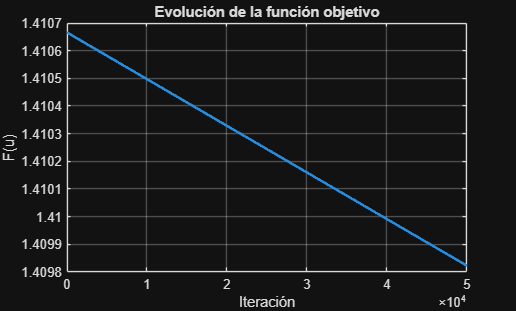

clc;
clear;
close all;

% Parámetros
n = 50;           % número de subintervalos (puede cambiarse)
h = 1/n;          % paso
alpha = 1e-7;     % paso del método de gradiente (puede ajustarse)
tol = 1e-6;       % tolerancia para la norma del gradiente
maxiter = 50000;  % número máximo de iteraciones

% Condiciones de contorno
u0 = 1;
un = 1;

% Inicialización de la solución
x = linspace(0,1,n+1);
y = 1 + 0.3*sin(pi*x);

% Asegurar los contornos exactos
y(1) = u0;
y(end) = un;

% Preparación para almacenar la historia de errores
err_hist = zeros(1, maxiter);
F_hist = zeros(1, maxiter);

% Función objetivo discreta
compute_F = @(u) h * sum( u(1:end-1) .* sqrt(1 + ((u(2:end)-u(1:end-1))/h).^2) );


% Bucle principal
for k = 1:maxiter

    % Gradiente numérico mediante diferencias finitas centradas
    grad = zeros(1,n-1);
    
    eps_fd = 1e-8;
    
    for i = 1:n-1
    
        u_plus = y;
        u_minus = y;
    
        % Perturbación positiva
        u_plus(i+1) = u_plus(i+1) + eps_fd;
    
        % Perturbación negativa
        u_minus(i+1) = u_minus(i+1) - eps_fd;
    
        % Aproximación de la derivada parcial
        grad(i) = (compute_F(u_plus) - compute_F(u_minus)) ...
                  /(2*eps_fd);
    
    end

    % Norma del gradiente (criterio de parada)
    error = norm(grad);
    err_hist(k) = error;

    % Evaluar la función objetivo
    F_hist(k) = compute_F(y);

    if error < tol
        break;
    end

    % Actualización de las variables interiores (manteniendo contornos)
    y(2:n) = y(2:n) - alpha * grad;

    % Asegurar que los contornos permanezcan exactamente satisfechos
    y(1) = u0;
    y(end) = un;
end

% Truncar historial hasta la iteración real
err_hist = err_hist(1:k);
F_hist = F_hist(1:k);

figure;
plot(F_hist,'LineWidth',2)
grid on
xlabel('Iteración')
ylabel('F(u)')
title('Evolución de la función objetivo')


% Resultados mostrados
fprintf('Iteraciones: %d\n', k);

Iteraciones: 50000


fprintf('Error final (norma del gradiente): %e\n', error);

Error final (norma del gradiente): 4.103822e-01


fprintf('Valor final de la función objetivo F: %e\n', F_hist(end));

Valor final de la función objetivo F: 1.409823e+00



% Gráficas: curva óptima y evolución del error
figure;
subplot(2,1,1);
plot(x, y, '-o', 'LineWidth', 2, 'MarkerSize', 4);
grid on;
xlabel('x');
ylabel('u(x)');
title('Curva óptima (solución discreta)');
ylim([min(y)-0.1 max(y)+0.1]);

`La curva obtenida presenta un comportamiento suave y simétrico respecto al intervalo considerado. El algoritmo converge hacia una solución estable que minimiza el área de la superficie de revolución bajo las restricciones fijadas.`

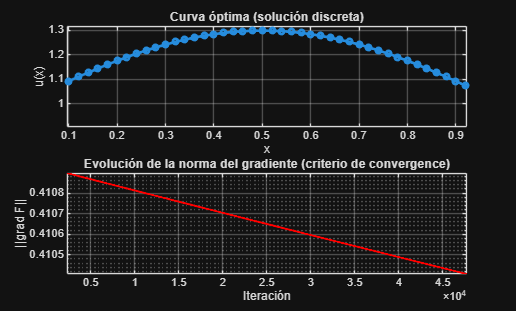

subplot(2,1,2);
semilogy(1:k, err_hist, '-r', 'LineWidth', 1.5);
grid on;
xlabel('Iteración');
ylabel('||grad F||');
title('Evolución de la norma del gradiente (criterio de convergence)');

`La norma del gradiente decrece progresivamente a medida que avanzan las iteraciones, lo que indica la convergencia del método de descenso del gradiente hacia un mínimo local de la función objetivo.`

### `Representación gráfica del solido de revolución generado`

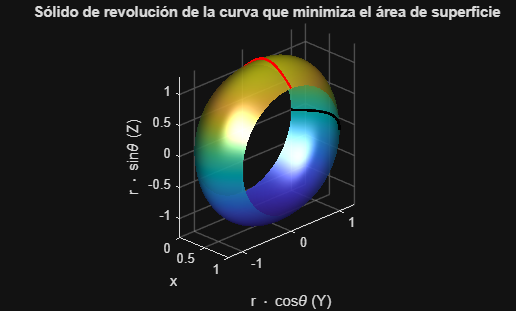

% Crear malla para la superficie de revolución
theta = linspace(0, 2*pi, 120);
[X,Theta] = meshgrid(x, theta);
Y = (interp1(x, y, X)).*cos(Theta);
Z = (interp1(x, y, X)).*sin(Theta);

% Grafica de la superficie
figure;
surf(X, Y, Z, 'FaceColor', 'interp', 'EdgeColor', 'none', 'FaceAlpha', 0.9);
colormap(parula);
hold on;
plot3(x, zeros(size(x)), y, 'r-', 'LineWidth', 2);
plot3(x, y, zeros(size(x)), 'k-', 'LineWidth', 2);
hold off;
axis equal;
xlabel('x');
ylabel('r \cdot cos\theta (Y)');
zlabel('r \cdot sin\theta (Z)');
title('Sólido de revolución de la curva que minimiza el área de superficie');
view(45,25);
lighting gouraud;
camlight headlight;


% Calculo del valor de la superficie
yprime = (y(2:end)-y(1:end-1))/h;
r = y(1:end-1);
area_intervals = 2*pi * r .* sqrt(1 + yprime.^2) * h;
area_total = sum(area_intervals);

fprintf('Área mínima del sólido de revolución: %e\n', area_total);

Área mínima del sólido de revolución: 8.858177e+00


## `Conclusiones y análisis de los resultados`

`Los resultados obtenidos muestran que el método del descenso del gradiente permite aproximar de forma estable la solución del problema planteado. La curva óptima calculada presenta un comportamiento suave y continuo, respetando las condiciones de contorno y generando un sólido de revolución geométricamente coherente.`

`La evolución de la función objetivo confirma que el algoritmo realiza correctamente pasos de descenso, ya que su valor disminuye progresivamente durante las iteraciones. Del mismo modo, la norma del gradiente presenta una reducción gradual, indicando convergencia hacia una solución estable.`

`La representación gráfica del sólido de revolución permite comprobar visualmente que la discretización y el método numérico implementado producen resultados consistentes tanto desde el punto de vista matemático como geométrico.`